rgb_monk = zeros(10,3);
rgb_monk(1,:) = rgb(246, 237, 228);
rgb_monk(2,:) = rgb(243, 231, 219);
rgb_monk(3,:) = rgb(247, 234, 208);
rgb_monk(4,:) = rgb(234, 218, 186);
rgb_monk(5,:) = rgb(215, 189, 150);
rgb_monk(6,:) = rgb(160, 126, 86);
rgb_monk(7,:) = rgb(130, 92, 67);
rgb_monk(8,:) = rgb(96, 65, 52);
rgb_monk(9,:) = rgb(58, 49, 42);
rgb_monk(10,:) = rgb(41, 36, 32);

lab_monk = rgb2lab(rgb_monk/255);

ita_monk = rad2deg(atan((lab_monk(:,1) - 50) ./ lab_monk(:,3)));

dist = 0.1;

%
% Fitzpatrick
%
rgb_fitzpatrick = zeros(6,3);
rgb_fitzpatrick(1,:) = [241 220 219];
rgb_fitzpatrick(2,:) = [229 185 200];
rgb_fitzpatrick(3,:) = [220 175 133];
rgb_fitzpatrick(4,:) = [162 127 97];
rgb_fitzpatrick(5,:) = [81 58 40];
rgb_fitzpatrick(6,:) = [10 9 7];
lab_fitzpatrick = rgb2lab(rgb_fitzpatrick/255);
ita_fitzpatrick = rad2deg(atan((lab_fitzpatrick(:,1) - 50) ./ lab_fitzpatrick(:,3)));
marker_fitzpatrick = {"I", "II", "III", "IV", "V", "VI"};

## 3D

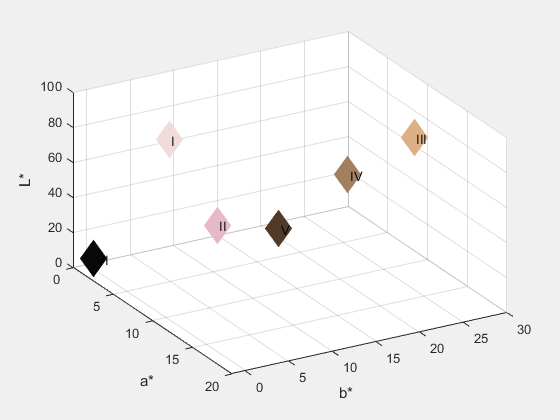

clf
hg = gcf;
set(gcf,'Visible','on')
hold on

for i=1:10
    plot3(lab_monk(i,2),lab_monk(i,3),lab_monk(i,1),'o','MarkerSize',20,'MarkerFaceColor',rgb_monk(i,:)/255,'MarkerEdgeColor',rgb_monk(i,:)/255)
    text(lab_monk(i,2)+dist,lab_monk(i,3)+dist,lab_monk(i,1),sprintf('%d',i))
end

for i=1:6
    plot3(lab_fitzpatrick(i,2),lab_fitzpatrick(i,3),lab_fitzpatrick(i,1),'d','MarkerSize',20,'MarkerFaceColor',rgb_fitzpatrick(i,:)/255,'MarkerEdgeColor',rgb_fitzpatrick(i,:)/255)
    text(lab_fitzpatrick(i,2)+dist,lab_fitzpatrick(i,3)+dist,lab_fitzpatrick(i,1),marker_fitzpatrick{i})
end

xlabel('a*')
ylabel('b*')
zlabel('L*')
grid on
view(60,35)

## Show ITA to answer Josh's question

lab_monk

lab_monk =    94.2111    1.5039    5.4302
   92.2748    2.0617    7.2881
   93.0911    0.2173   14.2122
   87.5733    0.4608   17.7549
   77.9022    3.4729   23.1415
   55.1428    7.7854   26.7444
   42.4700   12.3267   20.5334
   30.6783   11.6686   13.3380
   21.0695    2.6910    5.9667
   14.6102    1.4828    3.5276


ita_monk()

ans =    82.9977
   80.2184
   71.7465
   64.7073
   50.3284
   10.8849
  -20.1390
  -55.3822
  -78.3465
  -84.3077


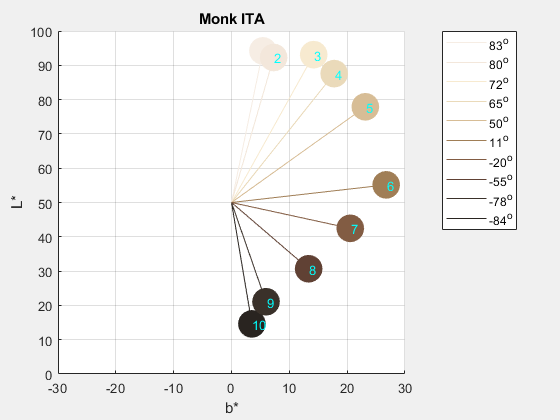


clf
hg = gcf;
set(gcf,'Visible','on')
hold on

% for i=1:10
% end

center = [0 0 50];

for i=1:10
    plot3(lab_monk(i,2),lab_monk(i,3),lab_monk(i,1),'o','MarkerSize',20,'MarkerFaceColor',rgb_monk(i,:)/255,'MarkerEdgeColor',rgb_monk(i,:)/255)
    text(lab_monk(i,2)+dist,lab_monk(i,3)+dist,lab_monk(i,1),sprintf('%d',i),'Color','c')

    lgn{(i-1)*2+1} = '';
    lgn{(i-1)*2+2} = sprintf('%.0f^o',ita_monk(i));

    p_from = center;
    p_to = [lab_monk(i,2) lab_monk(i,3) lab_monk(i,1)];
    p_from_to = [p_from; p_to];
    plot3(p_from_to(:,1),p_from_to(:,2),p_from_to(:,3),'-','Color',rgb_monk(i,:)/255)
end


axis([-30 30 -30 30 0 100])
xlabel('a*')
ylabel('b*')
zlabel('L*')
grid on
view([1 0 0])
title('Monk skin tone ITA')
legend(lgn)

saveas(hg,'monk_ita_on_Lb_plane.png')

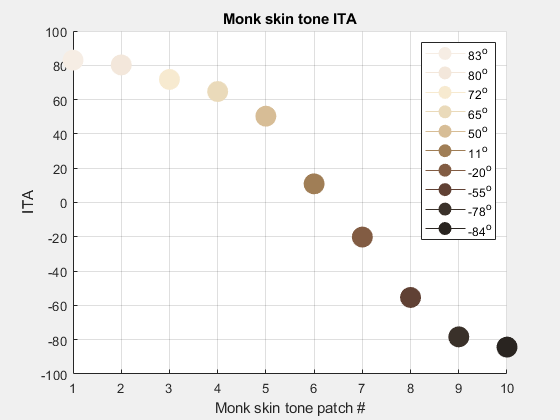


clf
hold on
lgn = {};
for i = 1:10
    plot(i,ita_monk(i),'o-', ...
        'MarkerFaceColor',rgb_monk(i,:)/255, ...
        'MarkerEdgeColor',rgb_monk(i,:)/255, ...
        'Color',rgb_monk(i,:)/255, ...
        'MarkerSize',15)
    lgn{i} = sprintf('%.0f^o',ita_monk(i));
end
grid on
legend(lgn)
xlabel('Monk skin tone patch #')
ylabel('ITA')
title('Monk skin tone ITA')

saveas(hg,'monk_ita_on_a_curve.png')

## Show ITA to answer Josh's question

lab_fitzpatrick

lab_fitzpatrick =    89.3943    7.0401    3.1064
   79.3444   18.1579   -1.5484
   74.5539   10.8187   27.7700
   55.8109    9.3193   21.4728
   26.5315    7.5715   15.1537
    2.4863   -0.0166    0.8491


ita_fitzpatrick()

ans =    39.3943    3.1064
   29.3444   -1.5484
   24.5539   27.7700
    5.8109   21.4728
  -23.4685   15.1537
  -47.5137    0.8491


ans =    85.4914
  -86.9795
   41.4827
   15.1425
  -57.1495
  -88.9763


ans =    85.4914
  -86.9795
   41.4827
   15.1425
  -57.1495
  -88.9763


ans =    85.4914
  -86.9795
   41.4827
   15.1425
  -57.1495
  -88.9763


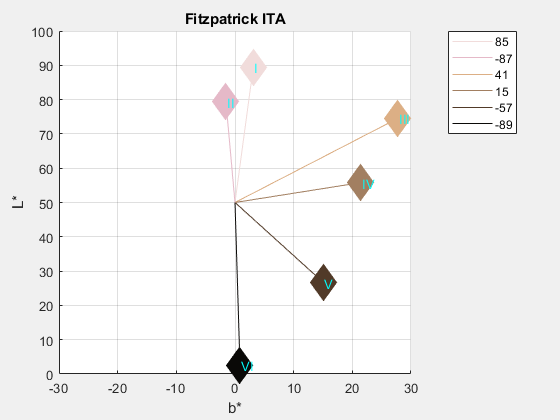


clf
hg = gcf;
set(gcf,'Visible','on')
hold on

% for i=1:10
%     plot3(lab_monk(i,2),lab_monk(i,3),lab_monk(i,1),'o','MarkerSize',20,'MarkerFaceColor',rgb_monk(i,:)/255,'MarkerEdgeColor',rgb_monk(i,:)/255)
%     text(lab_monk(i,2)+dist,lab_monk(i,3)+dist,lab_monk(i,1),sprintf('%d',i))
% end

center = [0 0 50];

for i=1:6
    plot3(lab_fitzpatrick(i,2),lab_fitzpatrick(i,3),lab_fitzpatrick(i,1),'d','MarkerSize',20,'MarkerFaceColor',rgb_fitzpatrick(i,:)/255,'MarkerEdgeColor',rgb_fitzpatrick(i,:)/255)
    text(lab_fitzpatrick(i,2)+dist,lab_fitzpatrick(i,3)+dist,lab_fitzpatrick(i,1),marker_fitzpatrick{i}, ...
        'Color','c')

    lgn{(i-1)*2+1} = '';
    lgn{(i-1)*2+2} = sprintf('%.0f',ita_fitzpatrick(i));

    p_from = center;
    p_to = [lab_fitzpatrick(i,2) lab_fitzpatrick(i,3) lab_fitzpatrick(i,1)];
    p_from_to = [p_from; p_to];
    plot3(p_from_to(:,1),p_from_to(:,2),p_from_to(:,3),'-','Color',rgb_fitzpatrick(i,:)/255)
end


axis([-30 30 -30 30 0 100])
xlabel('a*')
ylabel('b*')
zlabel('L*')
grid on
view([1 0 0])
title('Fitzpatrick ITA')
legend(lgn)



create_animation ('skin_color_in_CIELAB.gif')

function val = rgb (r,g,b)
    val = [r g b];
end

